# **线性极化波的演示**

**        电磁波的极化描述电磁波传播过程中电场强度的方向，确切地说，传播方向上任意点处的电场矢量端点随时间变化所描绘的轨迹称为极化。极化可分为线极化、圆极化和椭圆极化。线极化波的合成电场的大小虽随时间变化，但方向保持在一直线上，其动画制作可在二维平面内实现。圆极化波合成电场的大小不随时间变化，矢量的末端却在一个圆上以恒定角速度旋转。如果迎着波的传播方向看去，矢量沿逆时针方向旋转，称这种圆极化波为右旋圆极化波; 反之，若电场矢量是顺时针方向旋转的，则称为左旋圆极化波。**

**        考虑简单情形，假设均匀平面波沿**$+x$**方向传播，则电场强度矢量E的一般瞬时值和复矢量可分别表示为**


$$$$E=E_{_{ym}}\cos(\omega t-\beta x)e_{_y}+E_{_{zm}}\cos(\omega t-\beta x-\psi)e_{_z}$$$$



$$$$E=(E_{\mathrm{ym}}{e}_{y}+E_{zm}\mathrm{e}^{-\mathrm{j}\psi}{e}_{x})\mathrm{e}^{-\mathrm{j}\beta x}$$$$


**其中：**$$${\psi}$$$**是**$$$E_{z}$$$**分量滞后**$$$E_{y}$$$**分量的相位角。**

**        若电场强度E的两个横向分量的相位相同或反相，即**$$${\psi}=0$$$，**则电场强度各分量写为**


$$\begin{array}{l}
E_y =E_{ym} \cos (\omega t-\beta x)\\
E_z ={\pm E}_{zm} \cos (\omega t-\beta x)
\end{array}$$


**        取**$x=0$**的等相面观察，有**


$$\begin{array}{l}
E_y =E_{ym} \cos \omega t\\
E_z ={\pm E}_{zm} \cos \omega t
\end{array}$$


**        这是一个沿**$x$**方向传播的线性极化电磁波。它们的合成电场强度模值为**


$$$$E=\sqrt{E_{y}^{2}+E_{z}^{2}}=\sqrt{E_{ym}^{2}+E_{zm}^{2}}\cos\omega t$$$$


**        合成场强与**$x$**轴的夹角则为**


$$$$\varphi=\arctan\frac{E_{z}}{E_{y}}=\pm\arctan\frac{E_{zm}}{E_{ym}}$$$$


**        此时为线性极化波。**

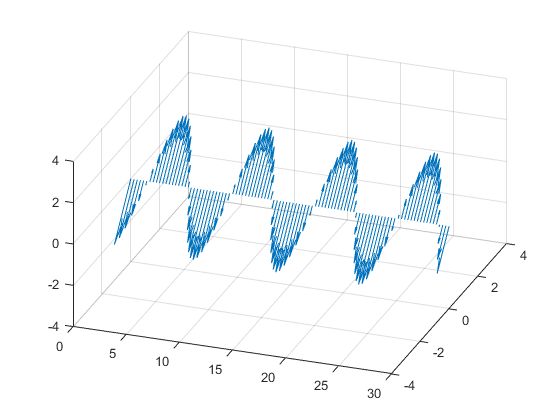

clc
clear
x=(0:0.3:30);                   	%传输距离
beta=0.8;
Eym=1;
Ezm=2;
l=zeros(size(x));                  	%设置l为与x尺寸相同的零向量
t=0;                            	%时间变量
for i=1:150                   	    %帧数
    omega=2*pi;
    Ey=Eym*cos(omega*t-beta*x);   	%电场横向y分量
    Ez=Ezm*cos(omega*t-beta*x);   	%电场横向z分量
    quiver3(x,l,l,l,Ey,Ez);           	%以(x,0,0)为起点画出传输方向上每一点的电场矢量图
    axis([0,30,-4,4,-4,4]); view(20,40); 	%观察范围
    mov(i)=getframe(gcf);           	%捕捉当前图像作为一帧
    t=t+0.05;                     	%时间变量变化微小量
end
hold off; 

- **动态展示**

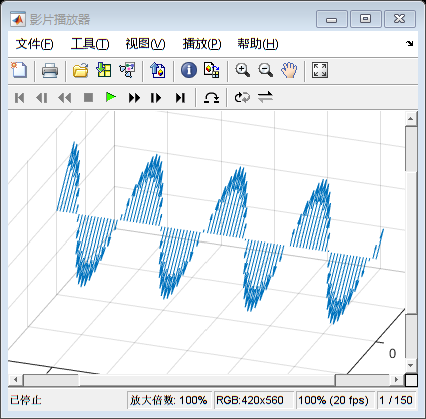

implay(mov);

- **保存为视频文件**

v=VideoWriter('线性极化波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)